% Recta y regresión

a= 2.5;
b = 1.8;

x = (0:1:10)';

y = a.*x + b + randn(size(x))

plot(x,y,'.','MarkerSize',10);
ylabel('Valor medido')
xlabel('Valor real')

% Vector de Regresores
R = [ones(size(x)) x]

R =      1     0
     1     1
     1     2
     1     3
     1     4
     1     5
     1     6
     1     7
     1     8
     1     9


ba = R\y

ba =     1.7891
    2.5911


a_est = ba(2)

a_est = 2.5911

b_est= ba(1)

b_est = 1.7891

y_est = a_est.*x + b_est

y_est =     1.7891
    4.3803
    6.9714
    9.5625
   12.1537
   14.7448
   17.3359
   19.9271
   22.5182
   25.1093


hold on
plot(x,y_est)
m=(y(end)-y(1))/(x(end)-x(1))

m = 2.3112

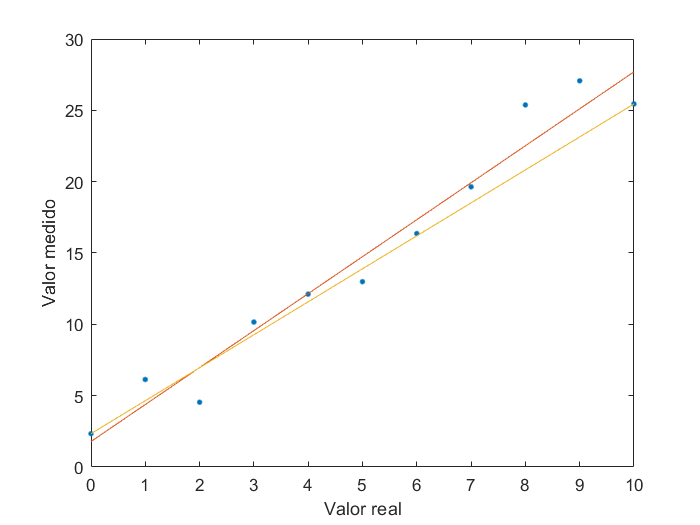

y_max = m.*x + y(1);
plot(x,y_max)

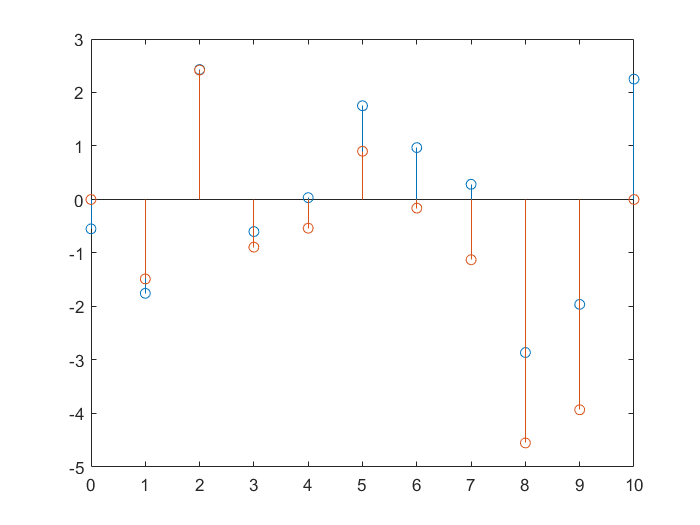

res_mc = y_est-y;
res_m = y_max-y;
figure
stem(x,[res_mc res_m])